%% Adapted from markostam Matlab ANC code
%Input
% M = learned filter length, dim 1x1
% x = input signal, dim Nx1
% d = desired signal, dim Nx1
% h = input coefficients  (coeff of filter we
%       are trying to learn. filter
%       that turns d into u)
%
% Output:
% e = estimation error, dim Nx1
% w = final filter coefficients, dim Mx1

% generate input signal
M=128; %buffer size (num filter weights)
x=randn(20000,1); %input signal
x=x/max(x); %sample rate
fs=44100; %number of samples of the input signal
N=length(x); %length of input signal

% loop through different mus to compare
mus = [0.01 0.05 0.1 0.5 1 2];
for j = 1:length(mus)
    % 100 epochs
    for i = 1:100
        curr_mu = mus(j);
        
        % generate known filter coefficients
        %linear coefficients
        P=(0.5*(0:127)).^2;  
        
%         y_lim = max(P)*1.20;
%         y_min = min(P)-.2*max(P);
        % generate filtered input signal == desired signal
        %input signal filtered by known filter P (primary path)
        d=conv(P,x); 
        
        
        %% LMS FOR Active Noise Cancel
        
        % initalize W filter values
        W=zeros(M,1);
        emean=zeros(N,1);
        %Make sure that x and d are column vectors
        x=x(:);
        d=d(:);

        %LMS
        for n=M:N
            %input has to be in reverse order
            xvec=x(n:-1:n-M+1); 
            %update error
            e(n)=d(n)-W'*xvec; 
            %update filter coefficient
            W=W+curr_mu*xvec*(e(n)); 
    % get convergence values        
        end
        e=e(:);
        emean = (emean(:)+e);
    end
    emean=(emean)/i;
    if sum(isinf(emean))>0
        emean(~isinf(emean))=1e3;
        eall(j,:)=emean;
    elseif max(emean)>1e4
        for l = 1:length(emean)
            if abs(emean(l)) > 1e3
                emean(l)=1e3;
            end
        end
        eall(j,:)=emean;
    else
        [eall(j,:),q]=(envelope(abs(emean),150,'peaks'));
    end
end

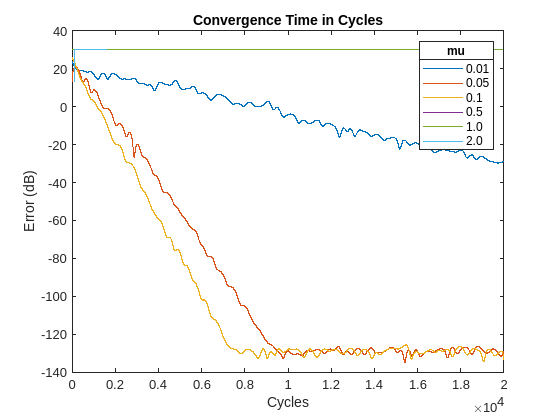

figure
for i = 1:length(mus)
    plot(10*log10(abs(eall(i,:))))
    hold on
end
title('Convergence Time in Cycles')
ylabel('Error (dB)');
xlabel('Cycles');
hleg=legend('0.01','0.05','0.1','0.5','1.0', '2.0');
htitle=get(hleg,'Title');
set(htitle,'String','mu');

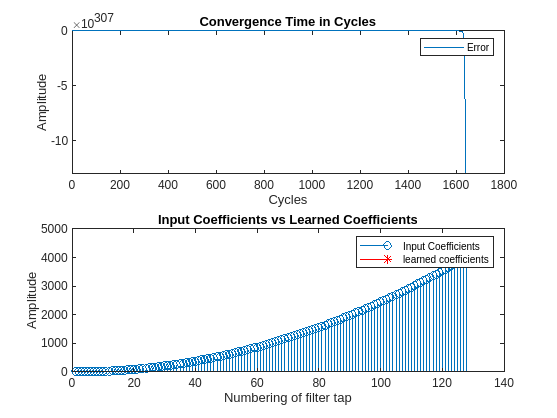

subplot(2,1,1)
plot(e)
title('Convergence Time in Cycles')
ylabel('Amplitude');
xlabel('Cycles');
legend('Error');
subplot(2,1,2)
stem(P)
hold on
stem(W, 'r*')
title('Input Coefficients vs Learned Coefficients')
ylabel('Amplitude');
xlabel('Numbering of filter tap');
legend('Input Coefficients', 'learned coefficients')